# **Sistemas  de Potencia - Condición en regimen permanente mediante Flujo de Carga**

Los flujos de carga son una herramienta eficaz basada en cálculo númerico para realizar un análisis del sistema de potencia. Gracias a su estudio se puede obtener la planificación, diseño y operación de una red eléctrica presente y futura pudiendo tener un mejor control de los cambios que en ella se generen.

En el siguiente modelo, se  plantea un SEP formado por 4 barras (subestaciones),  2 barras tipo PQ (subestaciones de inteerconexión con o sin cargas conectadas), una barra tipo PV (subestación de generación) y barra de referencia (subestación de generación). En dicho modelo se  desea conocer la condición de las  tensiones y corrientes para determinada condición de operación. A continuación, se presenta el procedimiento para obtener dichos valores.

- Entrada de datos básicos de las barras y ramas (líneas, transformadores y generadores).

- Formación  de la matriz de admitancia Ybus.

- Algoritmo  de Newton Raphson

- Resultados de condiciones de operación de las barras

- Resultados de corrientes en las líneas.

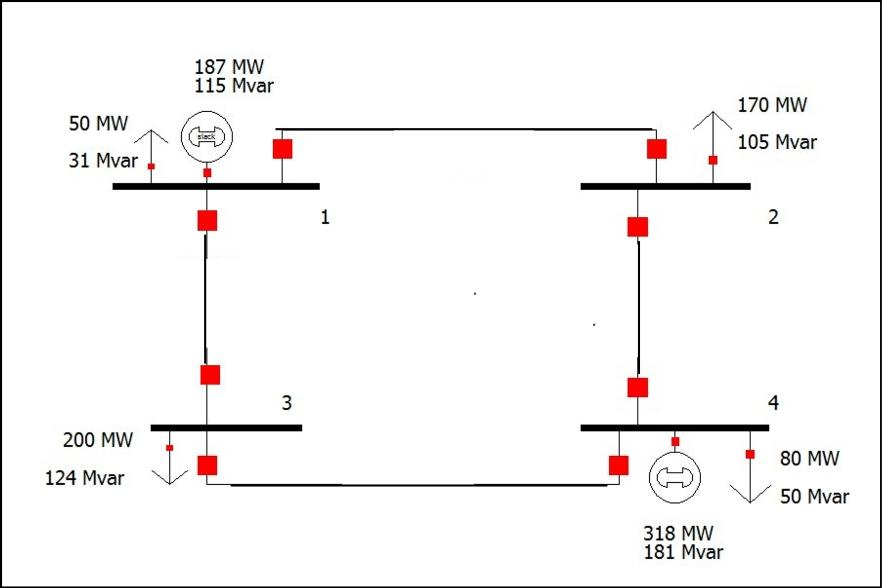

## **Entrada de datos básicos de las barras y ramas (líneas, transformadores y generadores)**

Los datos de las barras estan definidos en una matriz 4x12 en este caso particular, donde se establece en cada columna lo siguiente: 1- Número de barra, 2- Tipo de barra (0-PQ,1-slack, 2-PV), 3- Magnitud de tensión en pu, 4- ángulo de fase en rad, 5- Potencia activa de carga en pu,  6- Potencia reactiva de carga en pu, 7- Potencia activa de generación en pu, 8- Potencia reactiva de generación en pu, 9-Límite de generación reactiva máxima en pu, 10-Límite de generación reactiva mínima en pu, 11- Potencia reactiva de  reactancia en paralelo en pu, 12- Tensión nominal  de barra, como  dato general  se define una potencia base en MVA.

Sbase=100;

Sbase=100;
%        4 BUS TEST SYSTEM Monticelli Book Ref: 1-Slack 2-PV 0-PQ
%        Bus Bus  Voltage Angle   ---Load----     -----Generator--- StaticMvar
%        No  code Mag.    Degree    MW    Mvar    MW  Mvar Qmin Qmax     Qs       
data.bus=[1   1    1.00    0.0     50.0   30.99   0.0  0.0   0   0       0 110e3
          2   0    1.0     0.0    170.0  105.35   0.0  0.0   0   0       0 110e3
          3   0    1.0     0.0    200.0   23.94   0.0  0.0   0   0       0 110e3
          4   2    1.02    0.0     80.0   49.58 318.0  0.0   0   0       0 110e3 ];

Los datos  de las ramas vienen dados por una matrix 4x6 donde el numero de filas,   en este  modelo son las cuatro líneas,  donde las columnas definen: 1- barra desde de la rama, 2- barra hasta de rama, 3- resistencia de la rama en pu, 4- reactancia serie de la rama en pu, 5- Susceptancia media de la rama  en pu, 6- tap del transformador con relación a la barra desde en pu, en casode ser linea es igual a 1.

%                                                 Line code
%           Bus Bus   R         X         1/2 B   = 1 for lines
%            nd  nh  p.u.      p.u.      p.u.     > 1 or < 1 tr. tap at bus nl
data.branch=[1   2   0.01008   0.05040   0.05125    1
             1   3   0.00744   0.03720   0.03875    1
             2   4   0.00744   0.03720   0.03875    1
             3   4   0.01272   0.06360   0.06375    1];

## **Formación de la matriz de admitancias Ybus**

La matrizde admitancia Ybus es laque relaciona los voltajes y las corrientes inyectadas en cada barra, los elementos de la diagonal  esta formado por la suma de las admitancias conectadaa a la barra, es decir:


$$Y_{ii}=\sum_{j=1}^{nb}y_{ij}\space j\ne  i$$


En el caso de los elementos fuera de la diagonal, viene dado por el valor negativo de las  admitancias entre barras, es decir:


$$Y_{ij}=Y_{ji}=-y_{ij}$$


data.nd=data.branch(:,1);data.nh=data.branch(:,2);data.r=data.branch(:,3);
data.x=data.branch(:,4); data.bc=1i*data.branch(:,5);data.a=data.branch(:,6);
data.nbus = max([data.nd' data.nh']); % número total de barras
data.nram = length(data.nd); % número total de  ramas
data.y = 1./(data.r + 1i*data.x);% admitancia de rama
% Elementos de la Ybus fuera de la diagonal
Ybus=zeros(data.nbus,data.nbus);           
for k=1:data.nram
   Ybus(data.nd(k),data.nh(k))=Ybus(data.nd(k),data.nh(k))-data.y(k)/data.a(k);
   Ybus(data.nh(k),data.nd(k))=Ybus(data.nd(k),data.nh(k));
end
% Elementos de la Ybus en la diagonal          
for  n=1:data.nbus
     for k=1:data.nram
         if data.nd(k)==n
            Ybus(n,n) = Ybus(n,n) + data.y(k)/(data.a(k)^2) + data.bc(k);
         elseif data.nh(k)==n
            Ybus(n,n) = Ybus(n,n) + data.y(k) + data.bc(k);
         else
         end
     end
end
clear n k

## Algoritmo de Newton Raphson

Considerando que las potencias inyectadas en cada barra  obedecen a un sistema de ecuaciones no lineales, dado por.


$$P_{i}=\sum_{i=1}^{n}|V_{i}||V_{j}||Y_{ij}|\cos \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\\ 
Q_{i}=\sum_{i=1}^{n}|V_{i}||V_{j}||Y_{ij}|\sin \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )
$$


Newton Raphson (NR) establece soluciones lineales, mediante un proceso de linealización que solo considera el primer termino de la serie de Taylor  a partir de una condicion inicial dada, quedando lo siguiente:


$$\pmatrix{\Delta P_{2}^{(k)}\cr
\vdots \cr 
\Delta P_{n}^{(k)}\cr 
\Delta Q_{2}^{(k)}\cr
\vdots\cr
\Delta Q_{n}^{(k)}}=\pmatrix{
\frac{\partial P_{2}}{\partial \delta_{2}}^{(k)} & \cdots  & \frac{\partial P_{2}}{\partial \delta_{n}}^{(k)}& \frac{\partial P_{2}}{\partial |V_{2}|} ^{(k)}& \cdots & \frac{\partial P_{2}}{\partial |V_{n}|}^{(k)}\cr
 \vdots & \ddots  & \vdots  & \vdots  & \ddots  & \vdots \cr 
\frac{\partial P_{n}}{\partial \delta_{2}}^{(k)} & \cdots  & \frac{\partial P_{n}}{\partial \delta_{n}}^{(k)}& \frac{\partial P_{n}}{\partial |V_{2}|} ^{(k)}& \cdots & \frac{\partial P_{n}}{\partial |V_{n}|}^{(k)}\cr
\frac{\partial Q_{2}}{\partial \delta_{2}}^{(k)} & \cdots  & \frac{\partial Q_{2}}{\partial \delta_{n}}^{(k)}& \frac{\partial Q_{2}}{\partial |V_{2}|} ^{(k)}& \cdots & \frac{\partial Q_{2}}{\partial |V_{n}|}^{(k)}\cr
 \vdots & \ddots  & \vdots  & \vdots  & \ddots  & \vdots \cr 
\frac{\partial Q_{n}}{\partial \delta_{2}}^{(k)} & \cdots  & \frac{\partial Q_{n}}{\partial \delta_{n}}^{(k)}& \frac{\partial Q_{n}}{\partial |V_{2}|} ^{(k)}& \cdots & \frac{\partial Q_{n}}{\partial |V_{n}|}^{(k)}}\pmatrix{\Delta \delta_{2}^{(k)}\cr
\vdots \cr 
\Delta \delta_{n}^{(k)}\cr 
\Delta |V_{2}|^{(k)}\cr
\vdots\cr
\Delta |V_{n}|^{(k)}}
}
$$


Donde, la matriz Jacobiana es la que relaciona, los cambios asociados a las potencias activas y reactivas con las variaciones en los ángulos y magnitudes de las tensiones. Donde las dimensión de la matriz Jacobiana J, descartando la barra slack y las barras de tensión controlada m, siendo nb el numero total de barras queda en (2nb-2-m)x(2nb-2-m). Si definos la matriz Jacobina en cuatro submatrices se tiene que 


$$\pmatrix{\Delta P\cr 
\Delta Q}=\pmatrix{J_{1} & J_{2}\cr 
J_{3} & J_{4}}\pmatrix{\Delta \delta\cr 
\Delta |V|}$$


La submatriz J1 es de dimensión (nb-1)x(nb-1) los elementos en la diagonal y fuera de la diagonal, vienen dados por


$$\frac{\partial{P_{i}}}{\partial{\delta_{i}}}=\sum_{j\ne i}|V_{i}||V_{j}||Y_{ij}|\sin \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\\ 
\frac{\partial{P_{i}}}{\partial{\delta_{j}}}=-|V_{i}||V_{j}||Y_{ij}|\sin \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right ) \space j\ne i
$$


La submatriz J2 es de dimensión (nb-1)x(nb-1-m) los elementos en la diagonal y fuera de la diagonal, por


$$\frac{\partial{P_{i}}}{\partial{|V_{i}|}}=2|V_{i}||Y_{ii}|\cos \theta_{ii} + \sum_{j\ne i}|V_{j}||Y_{ij}|\cos \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\\ 
\frac{\partial{P_{i}}}{\partial{|V_{j}|}}=|V_{i}||Y_{ij}|\cos \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\space j\ne i
$$


La submatriz J3 es de dimensión (nb-1-m)x(nb-1) los elementos en la diagonal y fuera de la diagonal, por


$$\frac{\partial{Q_{i}}}{\partial{\delta_{i}}}= \sum_{j\ne i}|V_{i}||V_{j}||Y_{ij}|\cos \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\\ 
\frac{\partial{Q_{i}}}{\partial{\delta_{j}}}= -|V_{i}||V_{j}||Y_{ij}|\cos \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\space j\ne i
$$


La submatriz J4 es de dimensión (nb-1-m)x(nb-1-m) los elementos en la diagonal y fuera de la diagonal, por


$$\frac{\partial{Q_{i}}}{\partial{|V_{i}|}}=-2|V_{i}||Y_{ii}|\sin \theta_{ii} -\sum_{j\ne i}|V_{j}||Y_{ij}|\sin \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\\ 
\frac{\partial{Q_{i}}}{\partial{|V_{j}|}}=-|V_{i}||Y_{ij}|\sin \left ( \theta_{ij} -\delta _{i}+\delta _{j} \right )\space j\ne i
$$


Los cambios o mismatch de potencia definen la diferencia entre el  valor especificado en el caso de barras tipo PV o PQ y los valores calculados.


$$\matrix{\Delta P_{i}^{(k)}=P_{i}^{*}-P_{i}^{(k)}\cr

\Delta Q_{i}^{(k)}=Q_{i}^{*}-Q_{i}^{(k)}}
$$


Los nuevos valores estimados en las barras vienen dados por


$$\matrix{\delta_{i}^{(k+1)}=\delta_{i}^{(k)}+\Delta \delta_{i}^{(k)}\cr

|V_{i}^{(k+1)}|=|V_{i}^{(k)}|+\Delta |V_{i}^{(k)}|}
$$


El procedimiento para llevar a cabo el algoritmo  de NR es elsiguiente: 

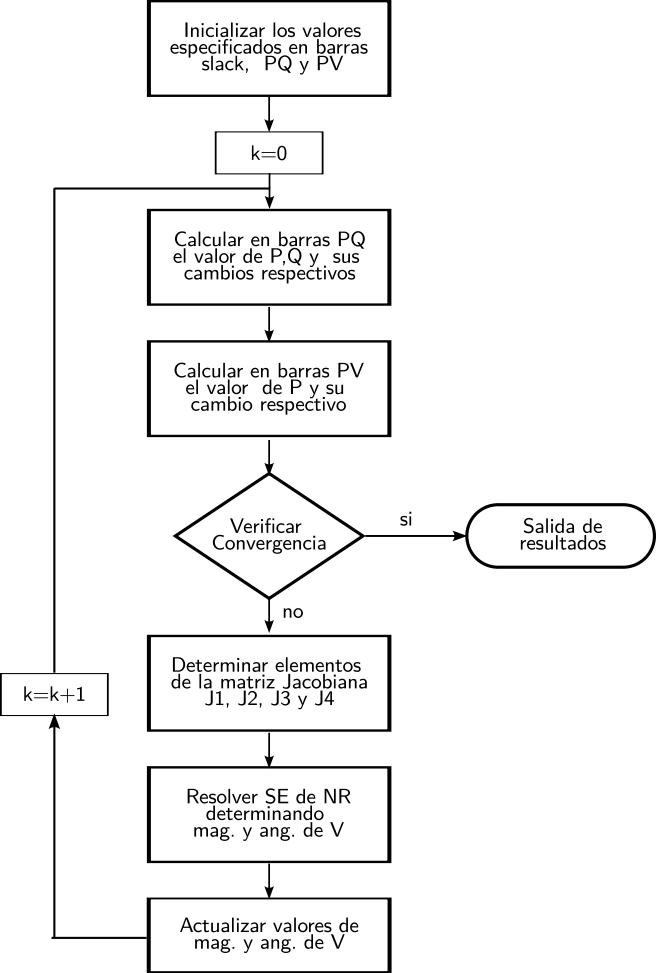

- Inicializar los valores, es decir para las barras de carga el valor de P y Q es especificado, la barra slack o referencia la magnitud y el angulo de la tensión son dados y donde se tiene tensión controlada la barra PV la  potencia activa y la magnitud de tensión es especificada.

- Calcular el valor de potencia  activa P y reactiva Q, posteriormente los cambios o mismatch de las potencias activas y reactivas en las barras de carga.

- Calcular el valor de potencia  activa P, posteriormente los cambios de potencia activa en las barras de tensión controlada.

- Determinar los  elementos de la matrix Jacobiana J1, J2, J3 y J4.

- Resolver el sistema de ecuaciones linealizado definiendo las variaciones  de la magnitud y ángulo de la tensión.

- Actualizar los valores  obtenidos para k+1.

- Repetir los pasos 2 y 3 con los nuevos valores, verificar convergencia, en caso de no cumplir repetir el proceso desde el paso 4

% Paso 1
nra.idb=[data.bus(:,1)];nra.tb=[data.bus(:,2)];
nra.pdb=[data.bus(:,5)];nra.qdb=data.bus(:,6);nra.pgb=data.bus(:,7);nra.qgb=data.bus(:,8);
nra.qmin=data.bus(:,9);nra.qmax=data.bus(:,10);nra.qsh=data.bus(:,11);nra.vb=data.bus(:,12);
% Valores de magnitud y angulo de tensiones iniciales
nra.vm=data.bus(:,3);
nra.ang=data.bus(:,4)*pi/180;
% valores de potencia activa y reactiva especificados
nra.pir=(nra.pgb-nra.pdb)/100;
nra.qir=(nra.qgb-nra.qdb+nra.qsh)/100;
% Paso 2
maxiter=100;tol=0.000001;maxerror=1;iter=0;

while maxerror>=tol && iter<=maxiter 
% Valor de potencia activa y reactiva calculada
    nra.Ybm=abs(Ybus);nra.Yba=angle(Ybus);
    for n=1:data.nbus
        kp=0;kq=0;
        for k=1:data.nbus
            nra.pic(n,1)=nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*cos(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kp;
            kp=nra.pic(n,1);
            nra.qic(n,1)=-nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*sin(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kq;
            kq=nra.qic(n,1);
        end
    end
    clear kp kq
    % Calculo de los mismatch de potencia
    nra.dP=nra.pir(nra.tb~=1)-nra.pic(nra.tb~=1);
    nra.dQ=nra.qir(nra.tb==0)-nra.qic(nra.tb==0);
    maxerror=max(abs([nra.dP;nra.dQ]));
    % Paso 3
    % Calculo de la matriz Jacobiana
    nra.J1=zeros(data.nbus,data.nbus);nra.J2=nra.J1;nra.J3=nra.J1;nra.J4=nra.J1;
    for n=1:data.nbus
        kp1=0;kp2=0;kq1=0;kq2=0;
        for k=1:data.nbus
            if n~=k
                % diagonal de  J1
                nra.J1(n,n)=nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*sin(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kp1;
                kp1=nra.J1(n,n);
                % fuera de diagonal J1
                nra.J1(n,k)=-nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*sin(nra.Yba(n,k)-nra.ang(n)+nra.ang(k));
                % diagonal J2
                nra.J2(n,n)=nra.vm(k)*nra.Ybm(n,k)*cos(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kp2;
                kp2=nra.J2(n,n);
                % fuera de diagonal J2
                nra.J2(n,k)=nra.vm(n)*nra.Ybm(n,k)*cos(nra.Yba(n,k)-nra.ang(n)+nra.ang(k));
                % diagonal de  J3
                nra.J3(n,n)=nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*cos(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kq1;
                kq1=nra.J3(n,n);
                % fuera de diagonal J3
                nra.J3(n,k)=-nra.vm(n)*nra.vm(k)*nra.Ybm(n,k)*cos(nra.Yba(n,k)-nra.ang(n)+nra.ang(k));
                % diagonal J4
                nra.J4(n,n)=-nra.vm(k)*nra.Ybm(n,k)*sin(nra.Yba(n,k)-nra.ang(n)+nra.ang(k))+kq2;
                kq2=nra.J4(n,n);
                % fuera de diagonal J4
                nra.J4(n,k)=-nra.vm(n)*nra.Ybm(n,k)*sin(nra.Yba(n,k)-nra.ang(n)+nra.ang(k));
            else
                kp2=kp2+2*nra.vm(n)*nra.Ybm(n,n)*cos(nra.Yba(n,n));
                kq2=kq2-2*nra.vm(n)*nra.Ybm(n,n)*sin(nra.Yba(n,n));
            end
        end
    end
    clear n k kp1 kp2 kq1 kq2
    nra.J1=nra.J1(nra.tb~=1,nra.tb~=1);
    nra.J2=nra.J2(nra.tb~=1,nra.tb==0);
    nra.J3=nra.J3(nra.tb==0,nra.tb~=1);
    nra.J4=nra.J4(nra.tb==0,nra.tb==0);
    nra.dPQ=[nra.dP;nra.dQ];
    nra.J=[nra.J1 nra.J2;nra.J3 nra.J4];
    nra.X=nra.J\nra.dPQ;
    nra.dang=nra.X(1:data.nbus-1);
    nra.dV=nra.X(data.nbus:end);
    nra.vm(nra.idb(nra.tb==0))=nra.vm(nra.idb(nra.tb==0))+nra.dV;
    nra.ang(nra.idb(nra.tb~=1))=nra.ang(nra.idb(nra.tb~=1))+nra.dang;
    iter=iter+1;
end


## Resultados de condición de operación en las barras

Los valores de lasmagnitudes  y angulos de tensión, la potencia activa y reactiva son los  siguientes

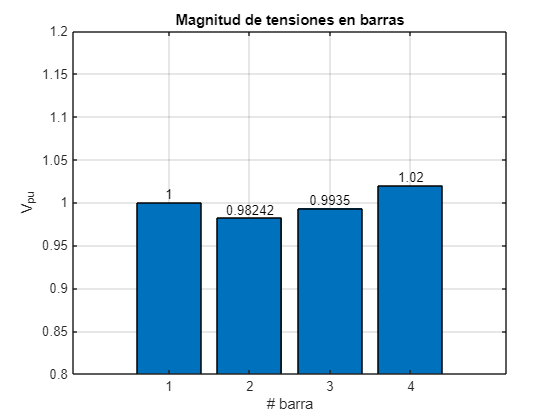

b=bar(nra.idb',nra.vm');
title('Magnitud de tensiones en barras')
xlabel('# barra')
ylabel('V_{pu}')
grid on
ylim([0.8 1.2])
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

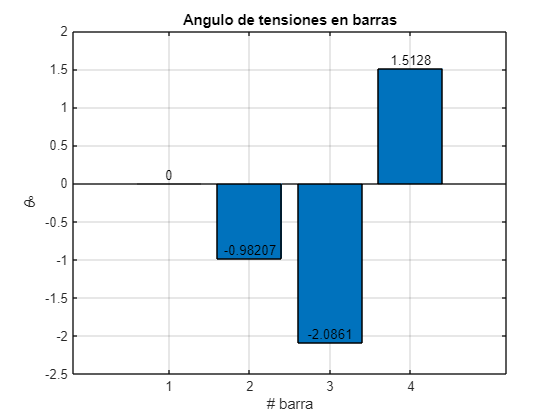


b=bar(nra.idb',(nra.ang*180/pi)');
title('Angulo de tensiones en barras')
xlabel('# barra')
ylabel('\theta_{º}')
grid on
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

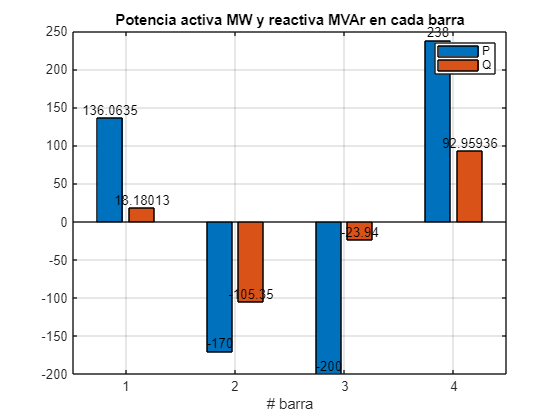

b=bar(nra.idb',[nra.pic'*Sbase;nra.qic'*Sbase]);
title('Potencia activa MW y reactiva MVAr en cada barra')
xlabel('# barra')
legend ('P','Q')
grid on
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

## Resultados de corrientes en las líneas

Los flujos de corriente y potencia de las líneas vienen dados por:


$$|I_{ij}|=|(V_{i}-V_{j})*y_{ij}+jB_c*V_{i}|$$


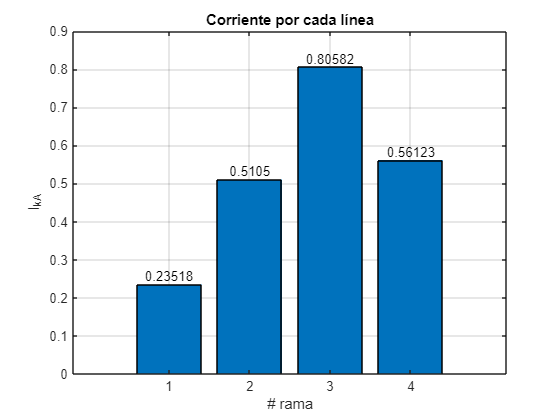

for n=1:data.nram
    Vi=nra.vm(data.nd(n))*(cos(nra.ang(data.nd(n)))+1i*sin(nra.ang(data.nd(n))));
    Vj=nra.vm(data.nh(n))*(cos(nra.ang(data.nh(n)))+1i*sin(nra.ang(data.nh(n))));
    Ibase=Sbase*1e6/(sqrt(3)*nra.vb(data.nd(n)));
    nra.Iram(n)=((Vi-Vj)*data.y(n)+data.bc(n)*Vi)*Ibase/1000;
end
x=1:data.nram;
b=bar(x',abs(nra.Iram'));
title('Corriente por cada línea')
xlabel('# rama')
ylabel('I_{kA}')
grid on
xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

clear Vi Vj x n xtips1 xtips2 ytips1 ytips2 labels1 labels2 b